# Polynomial Ridge Regression

Polynomial ridge regression is a regularized version of polynomial regression, to try to avoid overfitting. Larger values of the regularization parameter $\lambda$ restrains the regression weights (polynomial coefficients) to be smaller, and results in smoother polynomials.

Compare the following code to the code that we saw in `polynomial_regression`. To regularize polynomial regression, an augmented least squares problem is solved. The following code uses a degree 9 polynomial and different values of $\lambda$ from $10^{-10}$ to $10^{-2}$.

regularization parameter lambda 1e-10


w = 	1.0e+04 *

    0.0000
    0.0069
   -0.1029
    0.5969
   -1.6456
    2.1102
   -0.5896
   -1.4621
    1.5675
   -0.4812


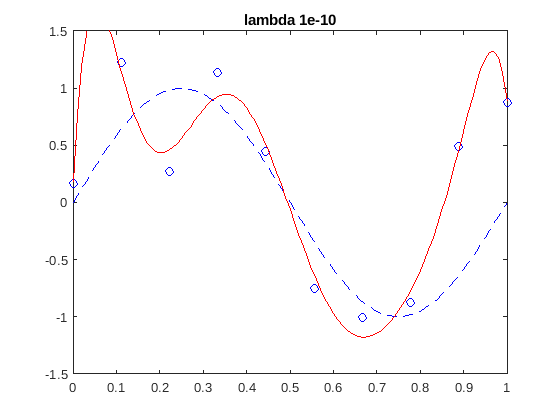

regularization parameter lambda 1e-08


w = 	1.0e+03 *

    0.0002
    0.0256
   -0.2701
    1.1362
   -2.0005
    0.8086
    1.1961
   -0.4376
   -1.0740
    0.6163


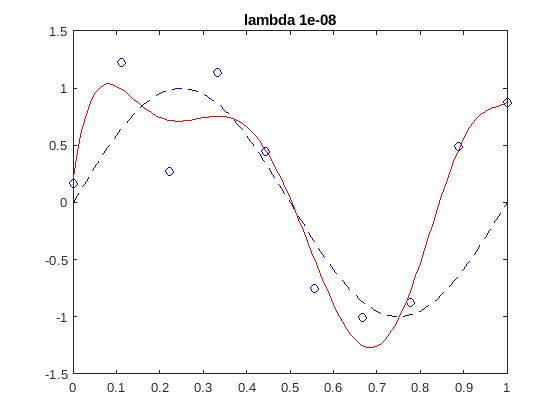

regularization parameter lambda 1e-06


w =     0.2722
    7.2504
  -29.0052
   63.0850
  -86.5295
  -13.8198
   60.0032
   51.5601
   -2.8429
  -49.1004


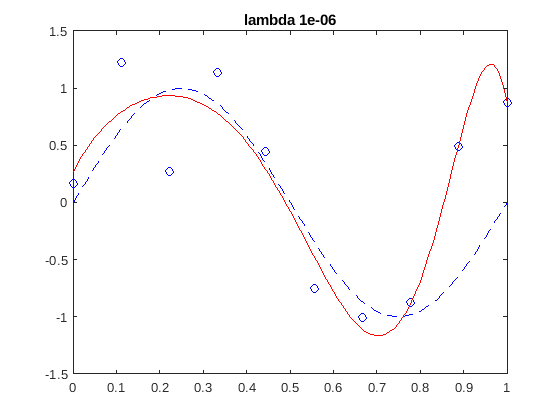

regularization parameter lambda 1e-04


w =     0.2552
    6.3009
  -10.8157
  -11.7455
   -1.0255
   11.3090
   16.1402
   11.3847
   -1.3479
  -19.5441


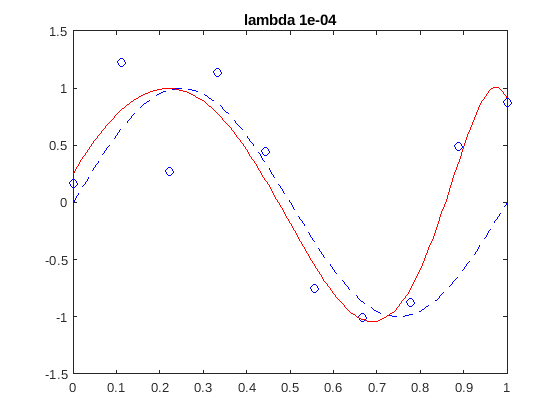

regularization parameter lambda 1e-02


w =     0.7034
    0.5252
   -3.9964
   -1.6324
    0.7273
    1.9369
    2.0713
    1.4404
    0.3337
   -1.0329


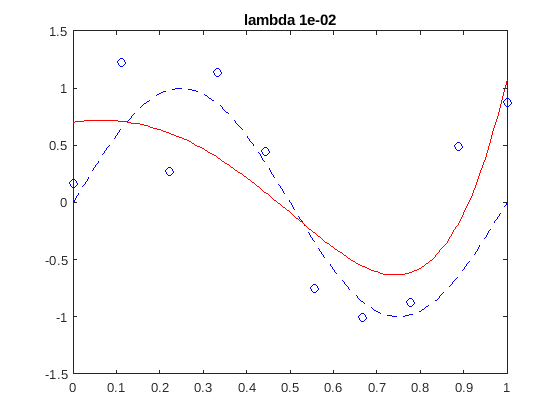

% generate synthetic data
fun = @(x) sin(2*pi*x); % true function
sigma2 = 0.1;           % noise variance
n = 10;                 % number of observations
delta = 1/(n-1);        % spacing between observations
x = (0:delta:1)';
y = fun(x) + sqrt(sigma2)*randn(size(x));

% least squares matrix
X = [ones(n,1) x x.^2 x.^3 x.^4 x.^5 x.^6 x.^7 x.^8 x.^9];
deg = 9;  % polynomial degree

% loop over different values of the regularization parameter
for ind = 10:-2:2
  lambda = 10^(-ind);  % regularization parameter

  % solve regularized least squares problem
  fprintf('regularization parameter lambda %.0e\n', lambda);
  w = [X; sqrt(lambda)*eye(deg+1)] \ [y; zeros(deg+1,1)]

  % calculate polynomial at values of xx
  xx = (0:.01:1)';
  yy = w(1)*ones(size(xx));
  for k = 1:deg
    yy = yy + w(k+1)*(xx.^k);
  end

  % plot the true function, the data, and the polynomial
  figure
  plot(xx,fun(xx),'b--', x,y,'bo', xx,yy,'r-');
  title(sprintf('lambda %.0e', lambda));
  axis([0 1 -1.5 1.5]);
end

Observe that the regression weights are smaller for larger values of $\lambda$ and the polynomial is smoother. For the largest value of $\lambda = 10^{-2}$, the polynomial is too restrained and does not have enough flexibility to fit the data as well as other values of $\lambda$. What value of $\lambda$ do is believe is best for fitting the true function?

### Taking it further

Experiment with different values of the noise variance. How does this affect the value of the regularization parameter $\lambda$ that you should choose?

Also experiment with different true functions, e.g., functions that are less smooth, where you may need more flexible models. Are there situations where polynomial ridge regression does not give a good model?